# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.7 获取 fig 文件数据

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/530658918/answer/2464535255](https://www.zhihu.com/question/530658918/answer/2464535255)

# matlab如何显示散点图的坐标（不是近似，我打开了一个.fig文件）？？

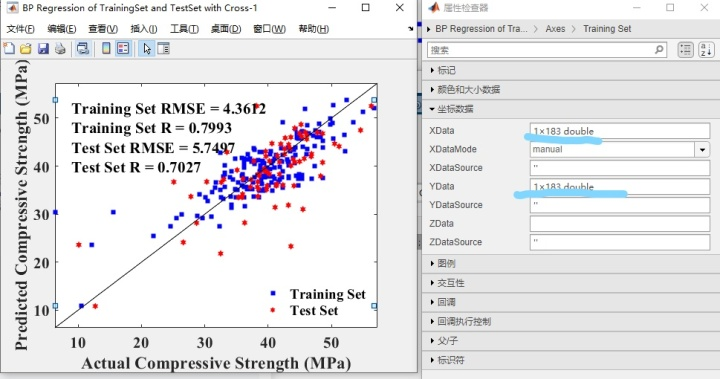

图片右边显示了183个坐标点，但是怎么把他们都显示出来呢？

clear;clc;
x = linspace(0, 2*pi, 100);
y1 = sin(x);
y2 = cos(x);
h = figure;
plot(x, y1, 'LineWidth', 2);
hold on
plot(x, y2, 'LineWidth', 2);
hold off
% 保存成 fig 文件
savefig(h, 'test.fig');
% 加载 fig 文件
fig = openfig('test.fig', 'invisible');
% 数据 figure --> axes --> plot
% ax = get(gcf, 'Children');
% plt = get(gca, 'Children');
x1 = fig.Children(1).Children(1).XData;
y1 = fig.Children(1).Children(1).YData;
x2 = fig.Children(1).Children(2).XData;
y2 = fig.Children(1).Children(2).YData;
figure;
plot(x1, y1, 'LineWidth', 2);
hold on
plot(x2, y2, 'LineWidth', 2);
hold off
